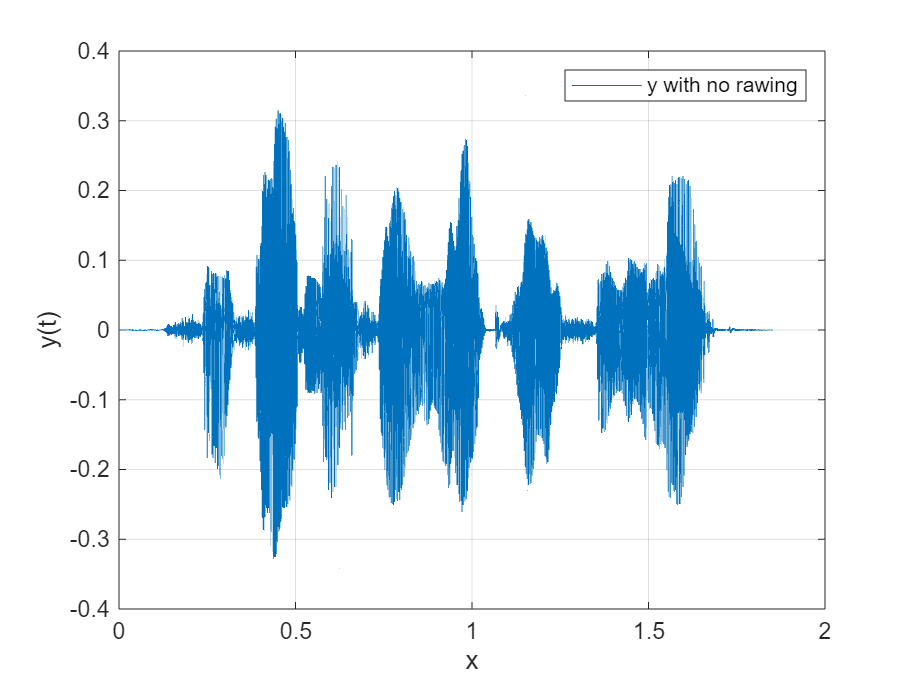

clc;
clear;
[x,fs] = audioread('C_01_02.wav');
x = x';
t = linspace(0,length(x)/fs,length(x));

figure;
plot(t,x);
xlabel('x'),
ylabel('y(t)'),
grid on;
legend('y with no rawing');

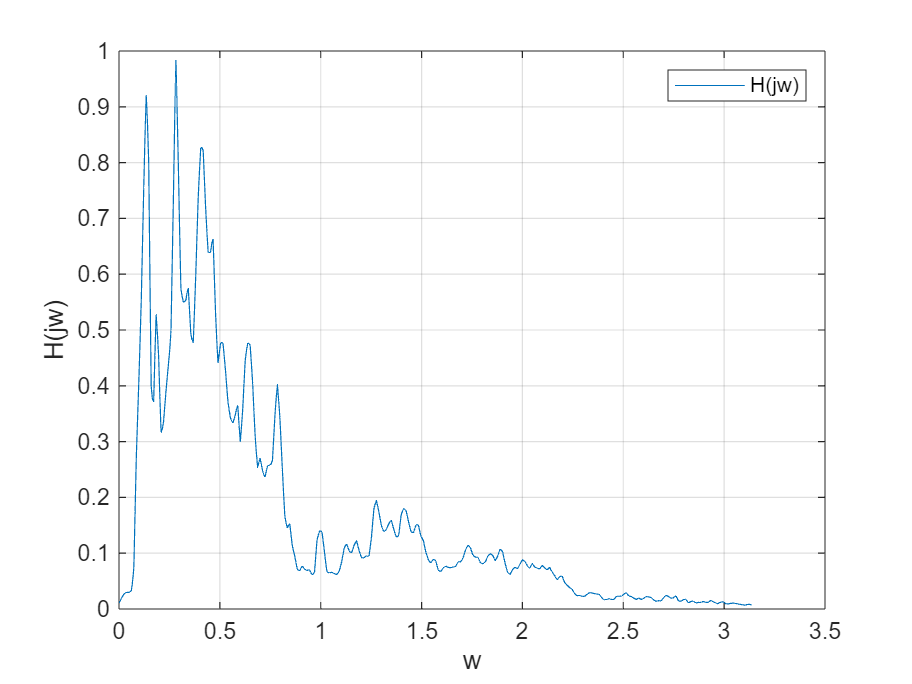


figure;
y10 = repmat(x,1,10);
nfft = 512;
noverlap = nfft/2;
window = hamming(nfft);
[P,w]=pwelch(y10,window,noverlap,nfft,fs);
b = fir2(3000,w/(fs/2),sqrt(P/max(P)));
[H,W] = freqz(b,1);
plot(W,abs(H));
xlabel('w'),
ylabel('H(jw)'),
grid on;
legend('H(jw)');

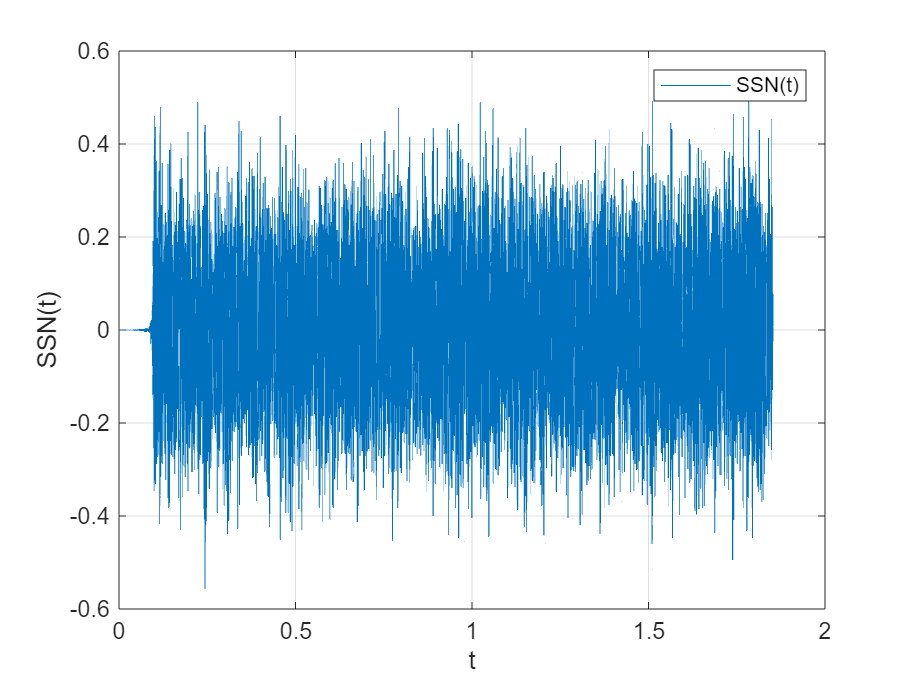


figure;
N = length(x);
noise = 1-2*rand(1,N);
SSN = filter(b,1,noise);
plot(t,SSN);
xlabel('t'),
ylabel('SSN(t)'),
grid on;
legend('SSN(t)');